# Tarea 1 parte 2 - Diego Alfaro Segura (C20259) Grupo 1

### Se carga la simulación

out = sim("simulinkTarea1_C20259.slx");

## Sección a) 

#### Gráfica de respuesta del sistema de control y(t).

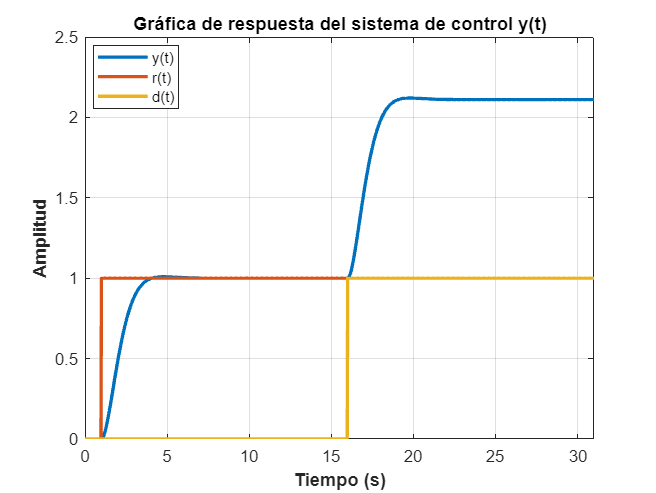

plot(out.y1,"LineWidth",2,'DisplayName',"y(t)")
hold on
plot(out.r1,"LineWidth",2,'DisplayName',"r(t)")
plot(out.d1,"LineWidth",2,'DisplayName',"d(t)")

% Personalización
grid on
legend('Location','best');
title("Gráfica de respuesta del sistema de control y(t)");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Amplitud",'FontWeight','bold');
xlim([0 31]);
hold off

#### Gráfica de la señal de control u(t).

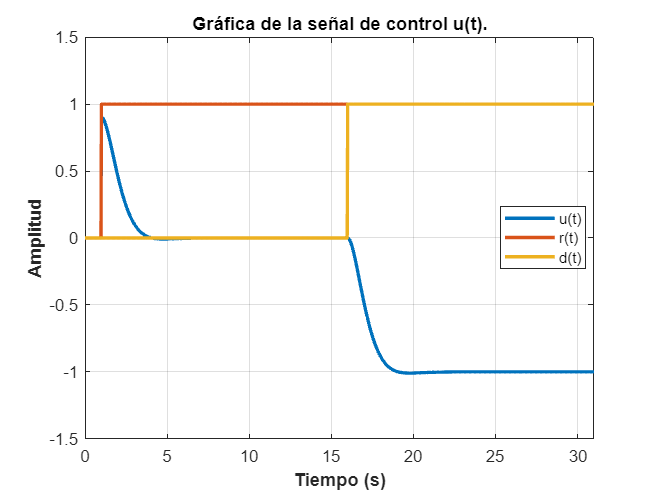

plot(out.u1, "LineWidth",2, 'DisplayName', "u(t)")
hold on
plot(out.r1, "LineWidth",2, 'DisplayName', "r(t)")
plot(out.d1, "LineWidth",2, 'DisplayName', "d(t)")

% Personalización
grid on
legend('Location','best');
title("Gráfica de la señal de control u(t).");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Amplitud",'FontWeight','bold');
xlim([0 31]);
ylim([-1.5 1.5]);
hold off

## Sección b)

#### Gráfica de respuesta del sistema de control y(t).

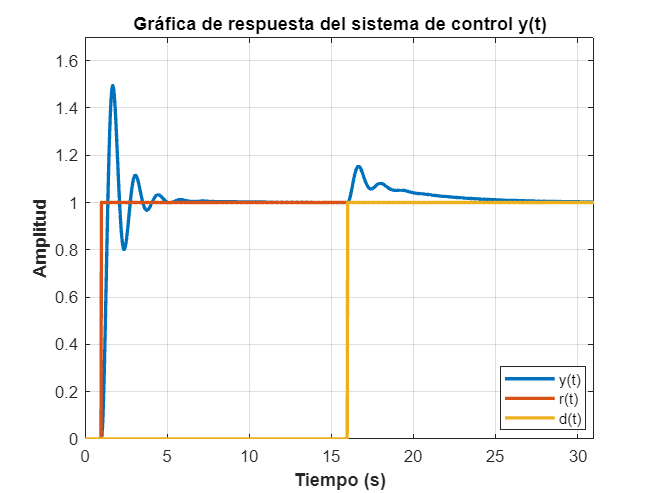

plot(out.y2, "LineWidth",2, 'DisplayName', "y(t)")
hold on
plot(out.r2, "LineWidth",2, 'DisplayName', "r(t)")
plot(out.d2, "LineWidth",2, 'DisplayName', "d(t)")

% Personalización
grid on
legend('Location','best');
title("Gráfica de respuesta del sistema de control y(t)");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Amplitud",'FontWeight','bold');
xlim([0 31]);
ylim([0 1.7]);
hold off

#### Gráfica de la señal de control u(t).

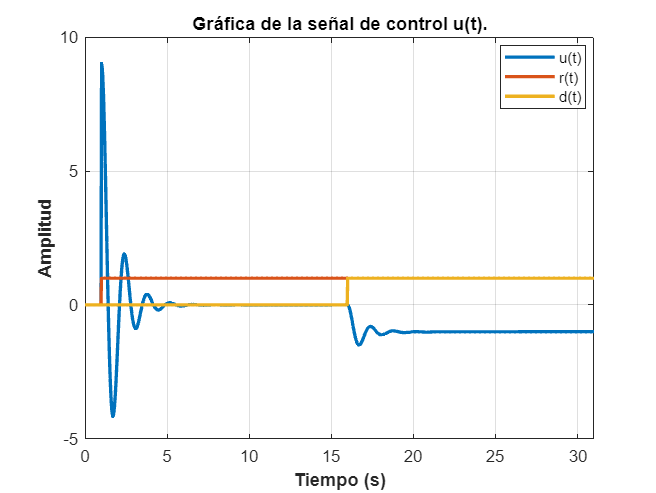

plot(out.u2, "LineWidth",2, 'DisplayName', "u(t)")
hold on
plot(out.r2, "LineWidth",2, 'DisplayName', "r(t)")
plot(out.d2, "LineWidth",2, 'DisplayName', "d(t)")

% Personalización
grid on
legend('Location','best');
title("Gráfica de la señal de control u(t).");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Amplitud",'FontWeight','bold');
xlim([0 31]);
hold off

## Sección c)

#### Figura comparativa entre las dos respuestas.

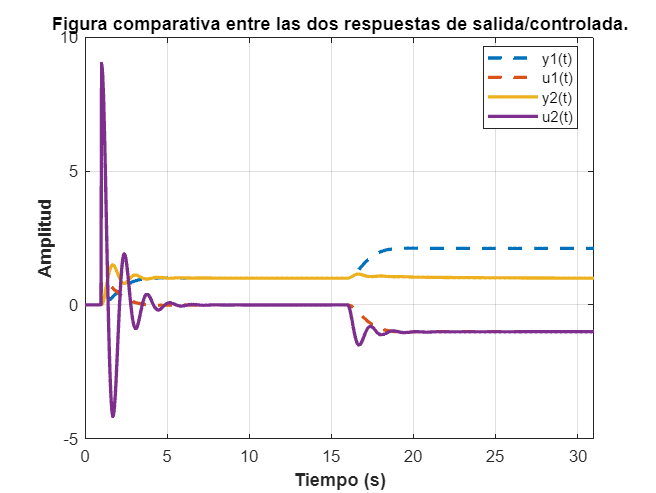

plot(out.y1, 'LineStyle', "--", "LineWidth",2, 'DisplayName', "y1(t)")
hold on
plot(out.u1, 'LineStyle', "--", "LineWidth",2, 'DisplayName', "u1(t)")
plot(out.y2, "LineWidth", 2, 'DisplayName', "y2(t)")
plot(out.u2, "LineWidth", 2, 'DisplayName', "u2(t)")

% Personalización
grid on
legend('Location','best');
title("Figura comparativa entre las dos respuestas de salida/controlada.");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Amplitud",'FontWeight','bold');
xlim([0 31]);
hold off

#### Obtención de polos y ceros de los lazos.

Se escriben las funciones de transferencia y los equivalentes de lazo cerrado para cada controlador.

P = tf(1,[0.4 1 0]);    % Planta
C1 = 0.9;               % Controlador con solo ganancia
C2 = tf([36 9], [4 0]); % Controlador modificado

% Lazos cerrados del primer controlador
Myd1 = P/(1+C1*P);
Myr1 = C1*Myd1;

% Lazos cerrados del segundo controlador
Myd2 = P/(1+C2*P);
Myr2 = C2*Myd2;

Ahora se muestran las gráficas de polos y ceros de cada uno.

#### Diagrama polos y ceros de Myd1:

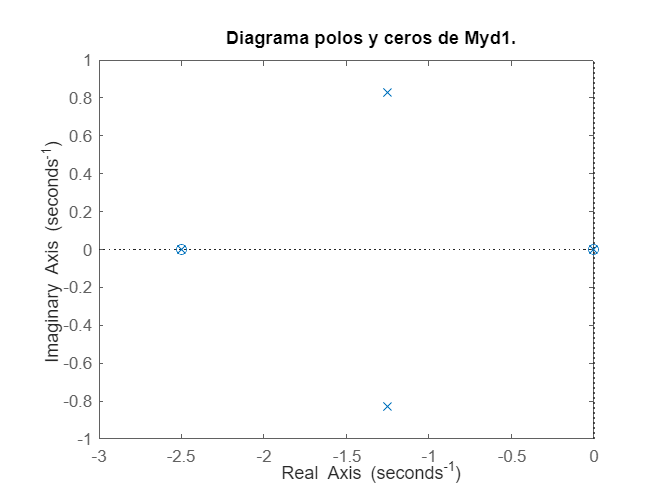

pzmap(Myd1);
hold on
xlim([-3 0])

% Personalización
title("Diagrama polos y ceros de Myd1.");
hold off

#### Diagrama polos y ceros de Myr1:

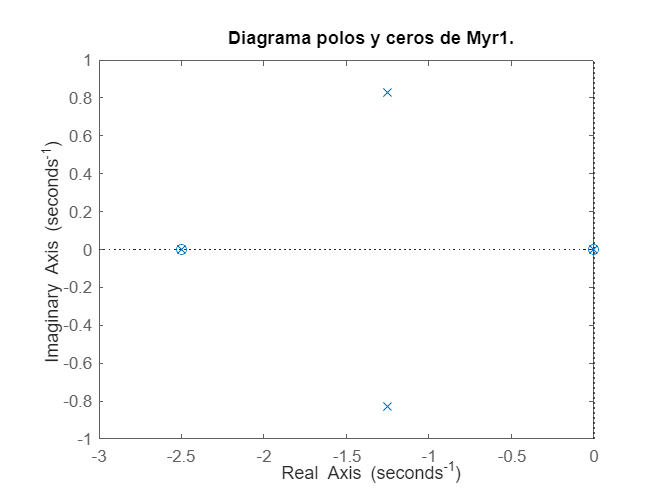

pzmap(Myr1);
hold on
xlim([-3 0])

% Personalización
title("Diagrama polos y ceros de Myr1.");
hold off

#### Diagrama polos y ceros de Myd2:

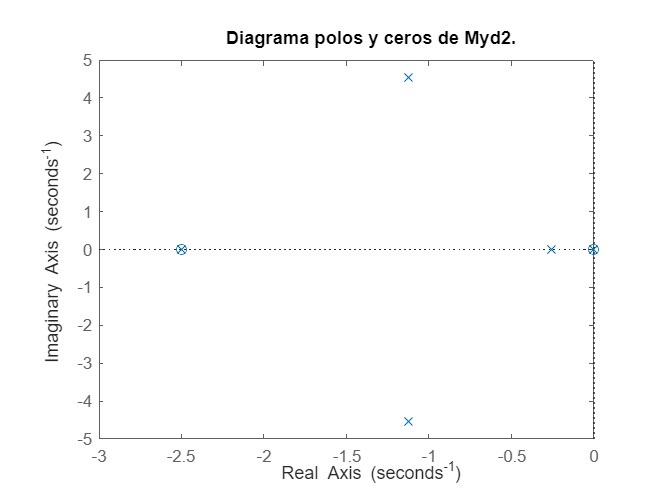

pzmap(Myd2);
hold on

% Personalización
title("Diagrama polos y ceros de Myd2.");
hold off

#### Diagrama polos y ceros de Myr2:

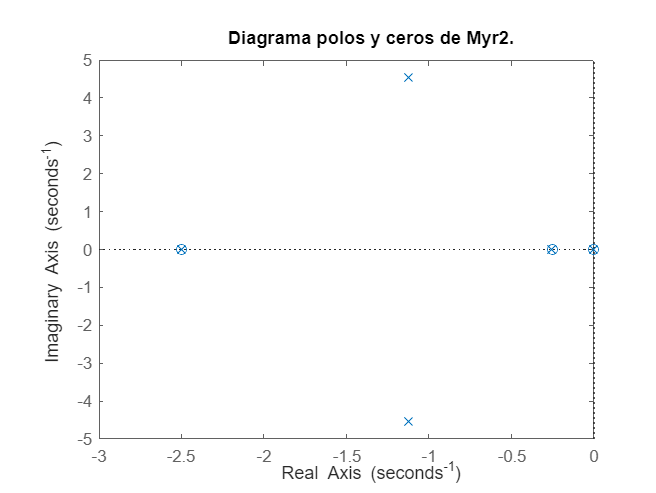

pzmap(Myr2);
hold on

% Personalización
title("Diagrama polos y ceros de Myr2.");
hold off

#### Extra: Comparación de funciones de transferencias de control regulatorio.

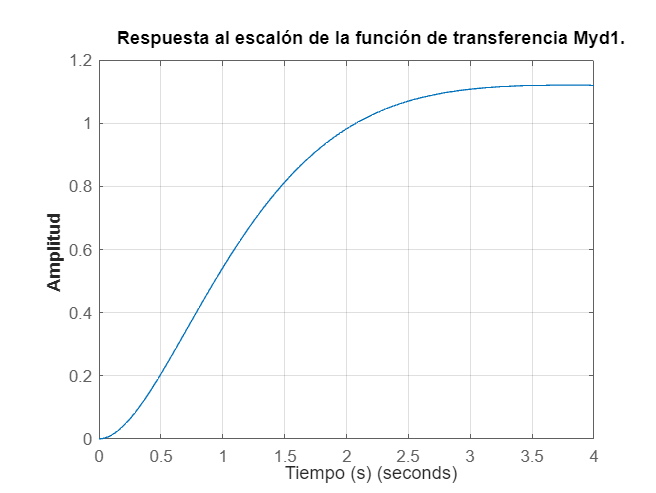

step(Myd1)
hold on

% Personalización
grid on
title("Respuesta al escalón de la función de transferencia Myd1.");
ylabel("Amplitud",'FontWeight','bold');
xlabel("Tiempo (s)")
hold off

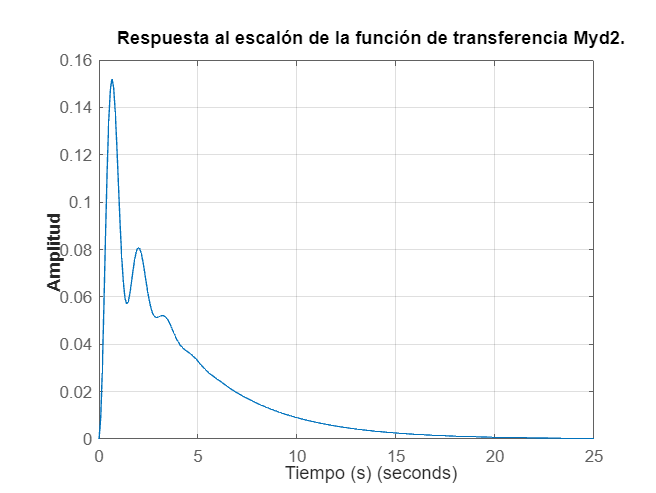


step(Myd2)
hold on

% Personalización
grid on
title("Respuesta al escalón de la función de transferencia Myd2.");
ylabel("Amplitud",'FontWeight','bold');
xlabel("Tiempo (s)")
hold off

#### Extra: Verificación de estabilización de funciones integradoras.

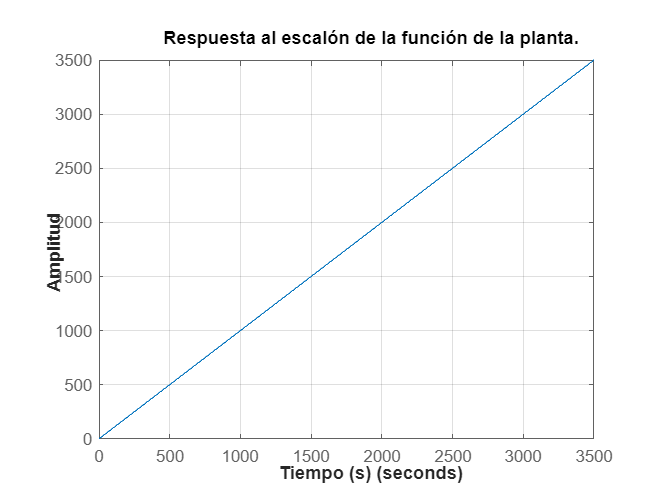

step(P)
hold on

% Personalización
grid on
title("Respuesta al escalón de la función de la planta.");
ylabel("Amplitud",'FontWeight','bold');
xlabel("Tiempo (s)",'FontWeight','bold')
hold off

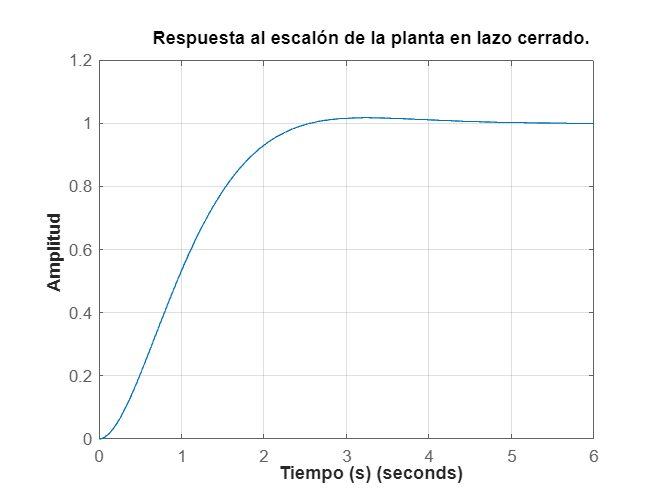


% Lazo cerrado de solo la planta
closedP = P/(1+P);

step(closedP)
hold on

% Personalización
grid on
title("Respuesta al escalón de la planta en lazo cerrado.");
ylabel("Amplitud",'FontWeight','bold');
xlabel("Tiempo (s)",'FontWeight','bold')
hold off